clear;

% Load configurations
fName = '2cup_freq';

unit = 10; % ml
if strcmp(fName, '1cup_freq')
    cup.height = 9; % centimeter
    cup.weight = 149.5;
    cup.maxAmount = 350;    
elseif strcmp(fName, '2cup_freq')
    cup.height = 10.5; % centimeter
    cup.weight = 180;
    cup.maxAmount = 450;
elseif strcmp(fName, '3cup_freq')
    cup.height = 9.8; % centimeter
    cup.weight = 315.7;
    cup.maxAmount = 390;
end

% Load data
fId = fopen([fName, '.txt']);
data.freq = cell2mat(textscan(fId, '%f'));
fclose(fId);

data.amount = [0:unit:cup.maxAmount]';

% Split train & test data
data.nTrain = 2;
indices = false(1, length(data.freq));
indices(ceil(linspace(1, length(data.freq), data.nTrain))) = true;

data.train.x = data.amount(indices);
data.train.y = data.freq(indices);

data.test.x = data.amount(~indices);
data.test.y = data.freq(~indices);

## French's law

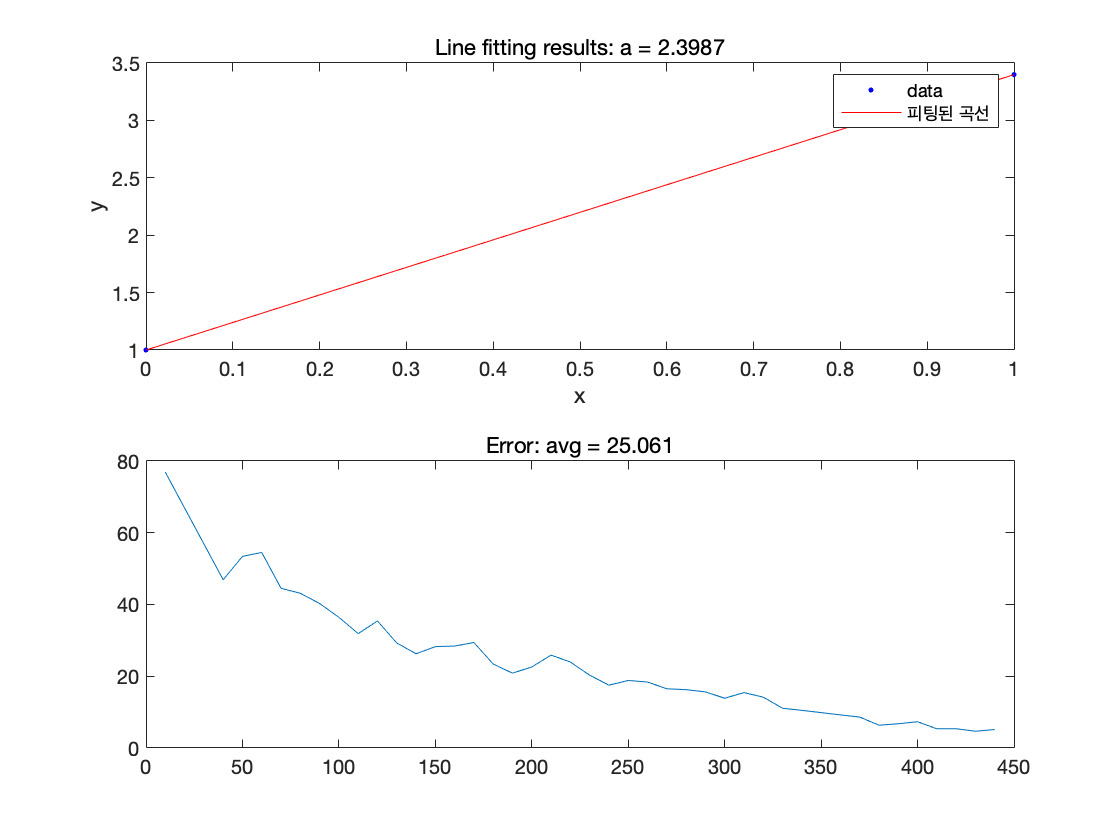

french.model = fittype('a*x + 1'); % y = 1 + ax

french.x = (data.train.x ./ cup.maxAmount).^4; % x = (m/M)^4 = (1 - d/H)^4
french.y = (data.train.y(1) ./ data.train.y).^2; % y = (f0 / f)^2

% Line fitting
french.f = fit(french.x, french.y, french.model, 'StartPoint', 0);

% Error estimation
french.estimated = ((data.train.y(1) ./ data.test.y).^2 - 1) / french.f.a; % x = (y - 1)/a
french.estimated = (french.estimated).^(1/4) * cup.maxAmount; % m = x^4 * M

french.err = abs(french.estimated - data.test.x);

subplot 211
plot(french.f, french.x, french.y)
title(['Line fitting results: a = ', num2str(french.f.a)])

subplot 212
plot(data.test.x, french.err)
title(['Error: avg = ', num2str(mean(french.err))])

## Weight-Freq relationship

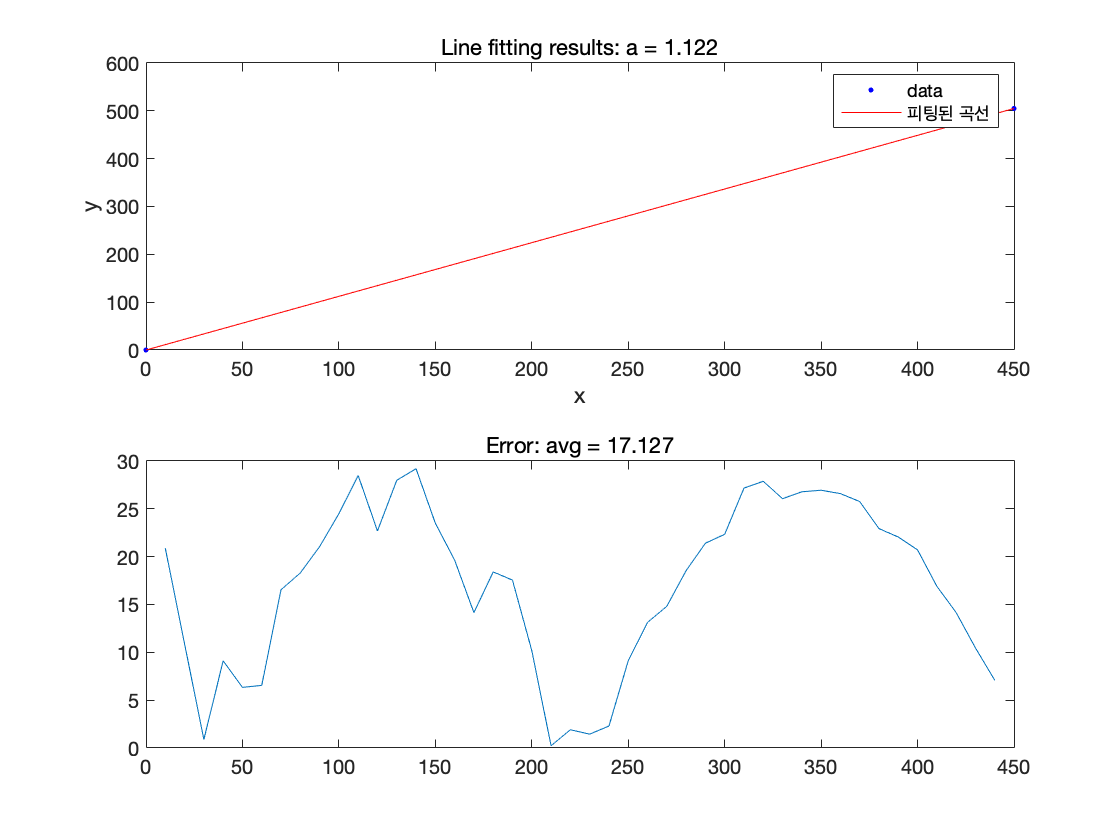

rel.model = fittype('a*x'); % y = ax

rel.x = data.train.x; % x = m
rel.y = sqrt(data.train.y(1)^2 - data.train.y.^2); % y = sqrt(f0^2 - f^2)

% Line fitting
rel.f = fit(rel.x, rel.y, rel.model, 'StartPoint', 0);

% Error estimation
rel.estimated = sqrt(data.train.y(1)^2 - data.test.y.^2) ./ rel.f.a; % m = x = y / a
rel.err = abs(rel.estimated - data.test.x); 

subplot 211
plot(rel.f, rel.x, rel.y)
title(['Line fitting results: a = ', num2str(rel.f.a)])
subplot 212
plot(data.test.x, rel.err)
title(['Error: avg = ', num2str(mean(rel.err))])